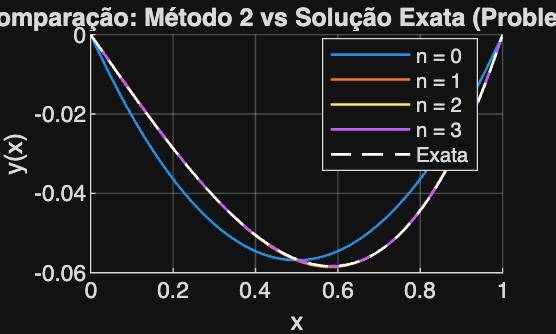

%b
%criar o grafico com as 5 funções
%i

format long

%funções q(x) e r(x) para o problema i
q = @(x) -1 + 0*x; 
r = @(x) x;

%solução exata do enunciado
yr1 = @(x) (exp(1+x) + x - x*exp(2) - exp(1-x)) / (exp(2) - 1);

x = linspace(0,1, 1000);

figure;
hold on;

for n = 0:3
    u= metodo2(n, q, r);
    ulista = arrayfun(u,x);
    
    %plot das aproximações
    plot(x, ulista, 'LineWidth', 1, 'DisplayName', ['n = ' num2str(n)]);
end


%plot da solução exata
plot(x, yr1(x), 'w--', 'LineWidth', 1, 'DisplayName', 'Exata');

xlabel('x');
ylabel('y(x)');
title('Comparação: Método 2 vs Solução Exata (Problema i)');
legend('Location', 'best');
grid on;
hold off;


errosib= zeros(1,4);
for n=0:3
    u=metodo2(n,q,r);
    t= @(x) (yr1(x) - u(x)).^2;
    errosib(:,n+1)= sqrt(integral(t,0,1));

end
errosib

errosib =    0.005612285919159   0.000148546950626   0.000015443132993   0.000000291820570


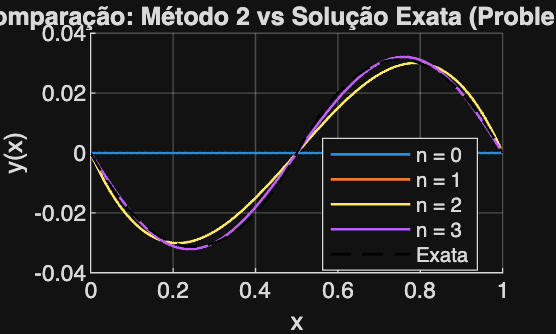

%ii
format long

%funções q(x) e r(x) para o problema ii
q = @(x) 0 * x;
r = @(x) (x >= 0 & x <= 0.5) * 1 + (x > 0.5 & x <= 1) * (-1);

%solução exata do problema ii
yr2 = @(x) (x >= 0 & x <= 0.5) .* (0.5 * x.^2 - 0.25 * x) + (x > 0.5 & x <= 1) .* (-0.5 * (x - 1).^2 - 0.25 * (x - 1));

x = linspace(0, 1, 1000);

figure;
hold on;

for n = 0:3
    u = metodo2(n, q, r);
    ulista = arrayfun(u, x);
    
    % plot das aproximações
    plot(x, ulista, 'LineWidth', 1, 'DisplayName', ['n = ' num2str(n)]);
end

% plot da solução exata
plot(x, yr2(x), 'k--', 'LineWidth', 1, 'DisplayName', 'Exata');

xlabel('x');
ylabel('y(x)');
title('Comparação: Método 2 vs Solução Exata (Problema ii)');
legend('Location', 'best');
grid on;
hold off;


errosiib= zeros(1,4);
for n=0:3
    u=metodo2(n,q,r);
    t= @(x) (yr2(x) - u(x)).^2;
    errosiib(:,n+1)= sqrt(integral(t,0,1));

end
errosiib

errosiib =    0.022821773229382   0.003049687727964   0.003049687727964   0.001053437285099
